# Intro to paths

### The Basics

Most programming languages and software, including MATLAB, use the concept of paths.

You have most likely encountered paths before, when looking for something in your directory. These can look something of the form:

`"C:\Users\nicol\MSc_TransNeuro_Mod3"`

Paths therefore indicate the path your computer has to follow, in order to find a desired folder or file in your memory. In MATLAB, you can see your current path at the top of the user interface:

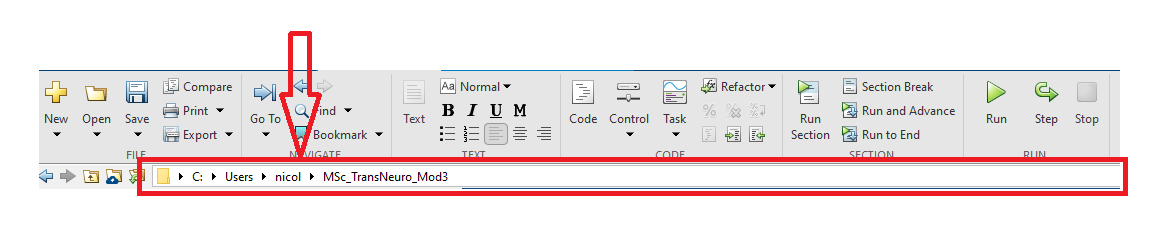

This allows MATLAB to know where to look for files.

### Syntax of Paths

Paths have a particular syntax, for both Mac and Windows, you can use 

"/"

ans = "/"

As the separator character between folders

**WINDOWS: **

In Windows paths start with your hard drive, which is given a letter, most commonly starting at *C: *

A common Windows path can look like: `"C:\Users\nicol\MSc_TransNeuro_Mod3"`

NOTE: Here the path separator is the backslash `"\"` instead of the normal slash `"/"`. This is because windows uses the backslash as default, but the normal slash still works in MATLAB.

**MAC/LINUX: **

In UNIX-based systems (MacOS or Linux), the paths start with a slash character `"/"`, followed by a series of folders.

An example of a common UNIX path can look like: `"/home/nicol/MSC_TransNeuro_Mod3".`

**Relative paths:**

You might have noted that in the previous examples, paths went all the way from the starting point of your memory, to the desired location. However, to make writing easier, you can use relative paths, which only indicate the path from your current location to your destination.

For example, if you wanted to access the "MyFolder`" `folder inside `"Functions"`, you could just type `"Functions/MyFolder"`

Relative paths also allow you to go backwards, by using the `".."` string. 

For example, accessing `"Functions/.."` is the same as accessing the current folder.

### Using paths in MATLAB

If MATLAB only used the path that you currently have open in the GUI's search bar at the top to look for files, it would be limited in use-cases.

To solve this, you use matlab's addpath function, to tell it where to look.

For example, if you try to run the following code:

my_sum(1,3) % This won't work

my_sum is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\nicol\MSc_TransNeuro_Mod3\Functions

Change the MATLAB current folder or add its folder to the MATLAB path.

You will receive an error message saying this function was not found in the path. This is because MATLAB does not have any function called `"my_sum"` by default.

To tell MATLAB where to find it, we can add the Functions folder to the path, and try again:

addpath("Functions") % Here we are using the relative path
my_sum(1,3) % This will work

You are amazing!
... and the sum is 4
Have a great day!


You can always undo this by using the following command:

rmpath("Functions")
my_sum(1,3) % This won't work again

my_sum is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\nicol\MSc_TransNeuro_Mod3\Functions

Change the MATLAB current folder or add its folder to the MATLAB path.

You can also check your current paths by using the following command, although the output might be quite long:

disp(path)

/home/nc619/Documents/MATLAB:/tmp/Editor_lqhxs:/usr/local/MATLAB/R2024b/toolbox/matlab/addon_enable_disable_management/matlab:/usr/local/MATLAB/R2024b/toolbox/matlab/addon_updates/matlab:/usr/local/MATLAB/R2024b/toolbox/matlab/addons:/usr/local/MATLAB/R2024b/toolbox/matlab/addons/cef:/usr/local/MATLAB/R2024b/toolbox/matlab/addons/fileexchange:/usr/local/MATLAB/R2024b/toolbox/matlab/addons/supportpackages:/usr/local/MATLAB/R2024b/toolbox/matlab/addons_common/matlab:/usr/local/MATLAB/R2024b/toolbox/matlab/addons_desktop_registration:/usr/local/MATLAB/R2024b/toolbox/matlab/addons_install_location/matlab:/usr/local/MATLAB/R2024b/toolbox/matlab/addons_product:/usr/local/MATLAB/R2024b/toolbox/matlab/addons_product_support/matlab:/usr/local/MATLAB/R2024b/toolbox/matlab/addons_registry/matlab:/usr/local/MATLAB/R2024b/toolbox/matlab/addons_sidepanel/matlab:/usr/local/MATLAB/R2024b/toolbox/matlab/addressbar_plugins/browse_for_folder_button/matlab:/usr/local/MATLAB/R2024b/toolbox/matlab/addressba